lena = imread("Lena_nb.jpg");
monde = imread("monde.png");
dominos = imread("dominos.png");
fig = 0;

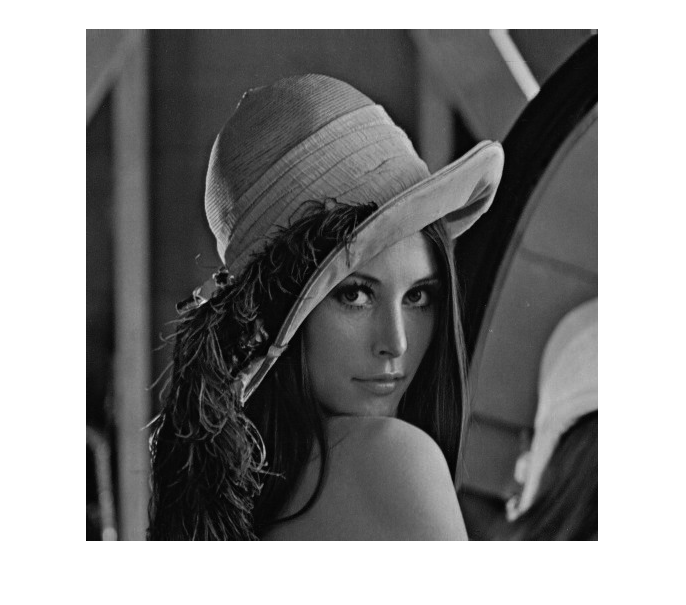

imshow(lena)

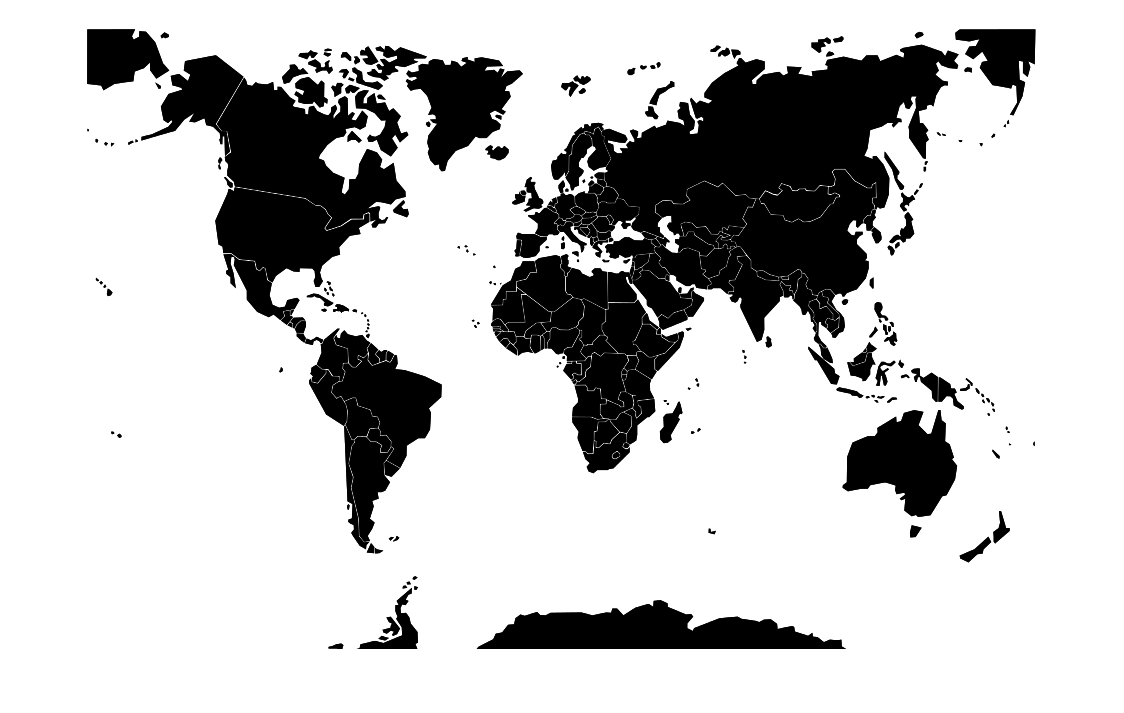

imshow(monde)

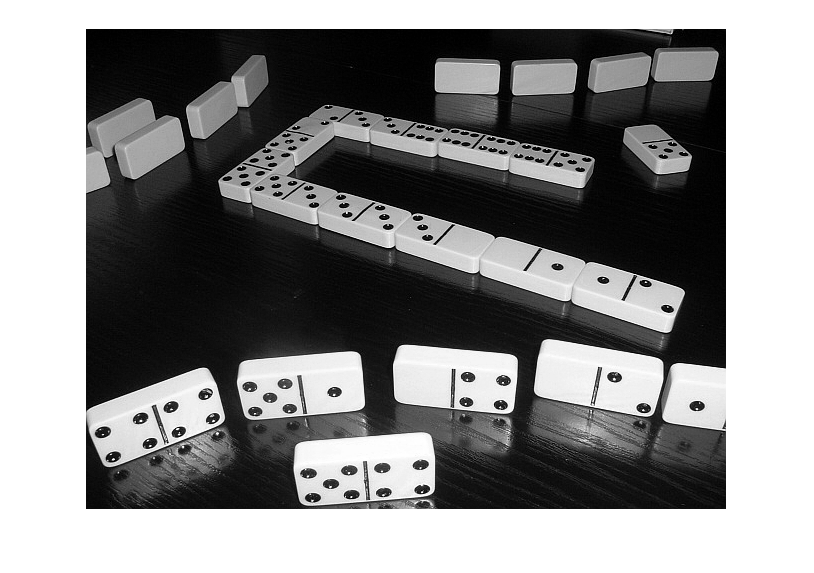

imshow(dominos)

## Filtres passe haut

h3 = [[-1 -1 -1];[0 0 0];[1 1 1]]

h3 =     -1    -1    -1
     0     0     0
     1     1     1


h4 = [[-1 -2 -1];[0 0 0];[1 2 1]]

h4 =     -1    -2    -1
     0     0     0
     1     2     1


h5 = [[0 1 0];[1 -4 1];[0 1 0]]

h5 =      0     1     0
     1    -4     1
     0     1     0


### Problème d'application du masque sur les bords de l'image

help conv2

 conv2 Two dimensional convolution.
    C = conv2(A, B) performs the 2-D convolution of matrices A and B.
    If [ma,na] = size(A), [mb,nb] = size(B), and [mc,nc] = size(C), then
    mc = max([ma+mb-1,ma,mb]) and nc = max([na+nb-1,na,nb]).
 
    C = conv2(H1, H2, A) first convolves each column of A with the vector
    H1 and then convolves each row of the result with the vector H2.  If
    n1 = length(H1), n2 = length(H2), and [mc,nc] = size(C) then
    mc = max([ma+n1-1,ma,n1]) and nc = max([na+n2-1,na,n2]).
    conv2(H1, H2, A) is equivalent to conv2(H1(:)*H2(:).', A) up to
    round-off.
 
    C = conv2(..., SHAPE) returns a subsection of the 2-D
    convolution with size specified by SHAPE:
      'full'  - (default) returns the full 2-D convolution,
      'same'  - returns the central part of the convolution
                that is the same size as A.
      'valid' - returns only t

Etant donné que les filtres "agissent" sur l'image par leur pixel central, les bords de l'image risquent de poser problème. En effet, il faut choisir entre n'appliquer le filtre que sur l'image (et donc ne pas réaliser de convolution sur les pixels au bord de l'image) ou ajouter des pixels après le bord de l'image (un padding) pour pouvoir appliquer le filtre sur les bords. La fonction *conv2* permet de faire ça automatiquement par l'attribut *SHAPE*.

Afin d'appliquer le filtre sur l'entièreté de l'image, nous avons décidé d'utiliser le paramètre *SHAPE = 'same'*.

### Application des filtres H3 et H4

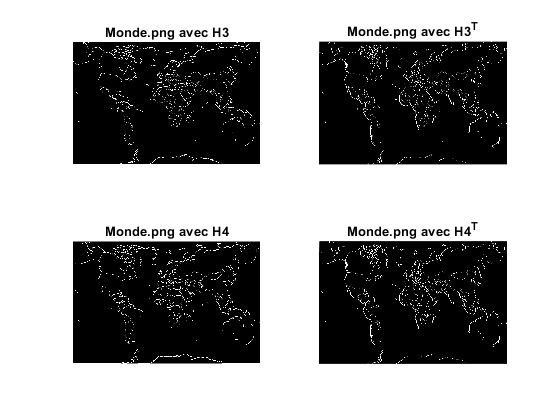

fig = fig + 1;
figure(fig);
subplot(2, 2, 1), convol(monde, h3, false), title('Monde.png avec H3')
subplot(2, 2, 2), convol(monde, h3', false), title('Monde.png avec H3^T')
subplot(2, 2, 3), convol(monde, h4, false), title('Monde.png avec H4')
subplot(2, 2, 4), convol(monde, h4', false), title('Monde.png avec H4^T')

Le fait d'appliquer une seule fois (et ne pas appliquer leur transposée) les filtres h3 ou h4 sur l'image ne permet de détecter qu'une partie des contours présents dans l'image, ce qui explique la présence de lignes discontinues.

### Détection des contours diagonaux avec H3

h3_d = [[0 1 2];[-1 0 1];[-2 -1 0]]

h3_d =      0     1     2
    -1     0     1
    -2    -1     0


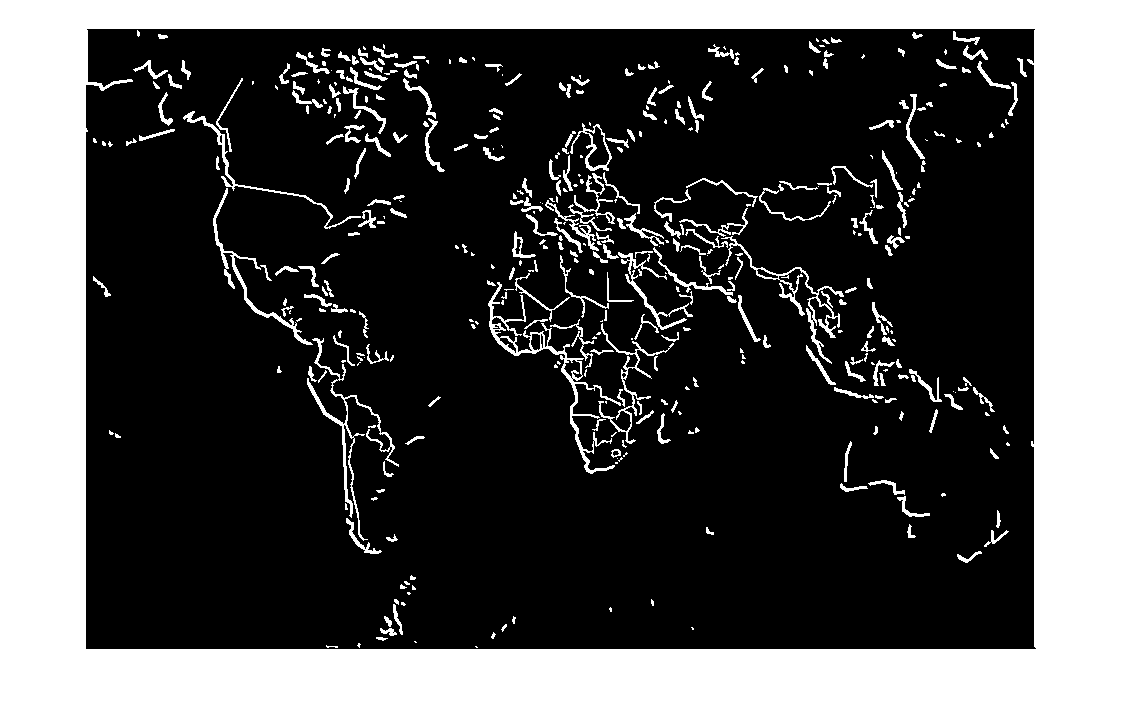

convol(monde, h3_d, false)

### Doubles convolutions vs H5

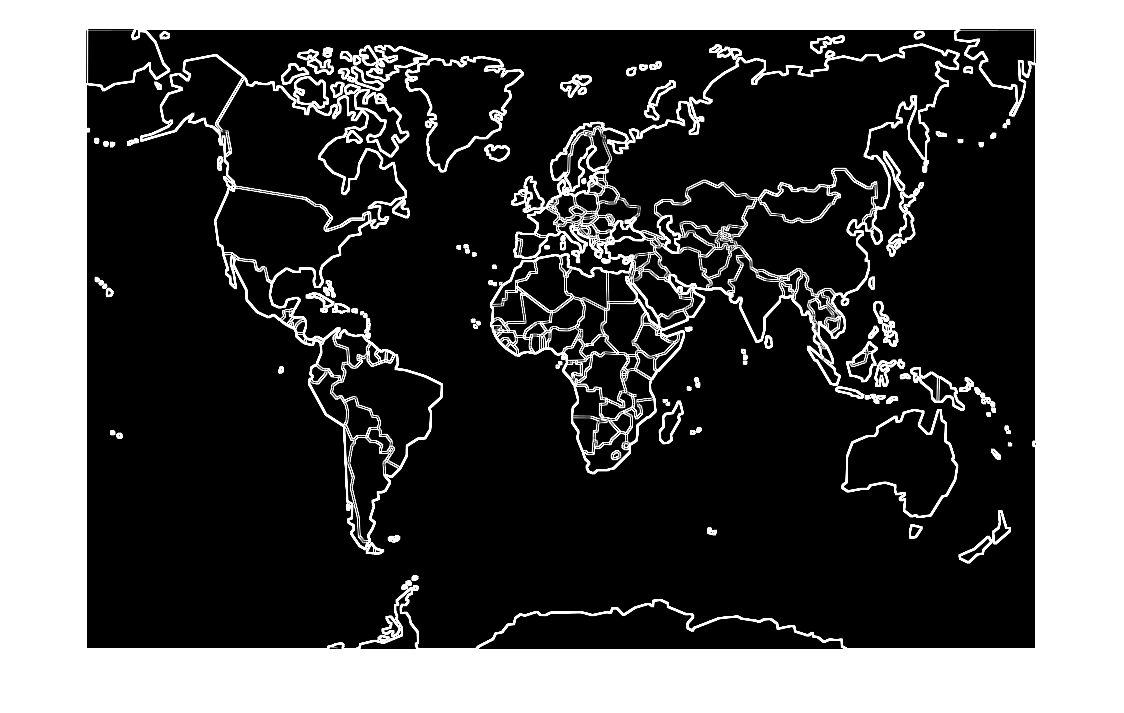

convol(monde, h3, true)

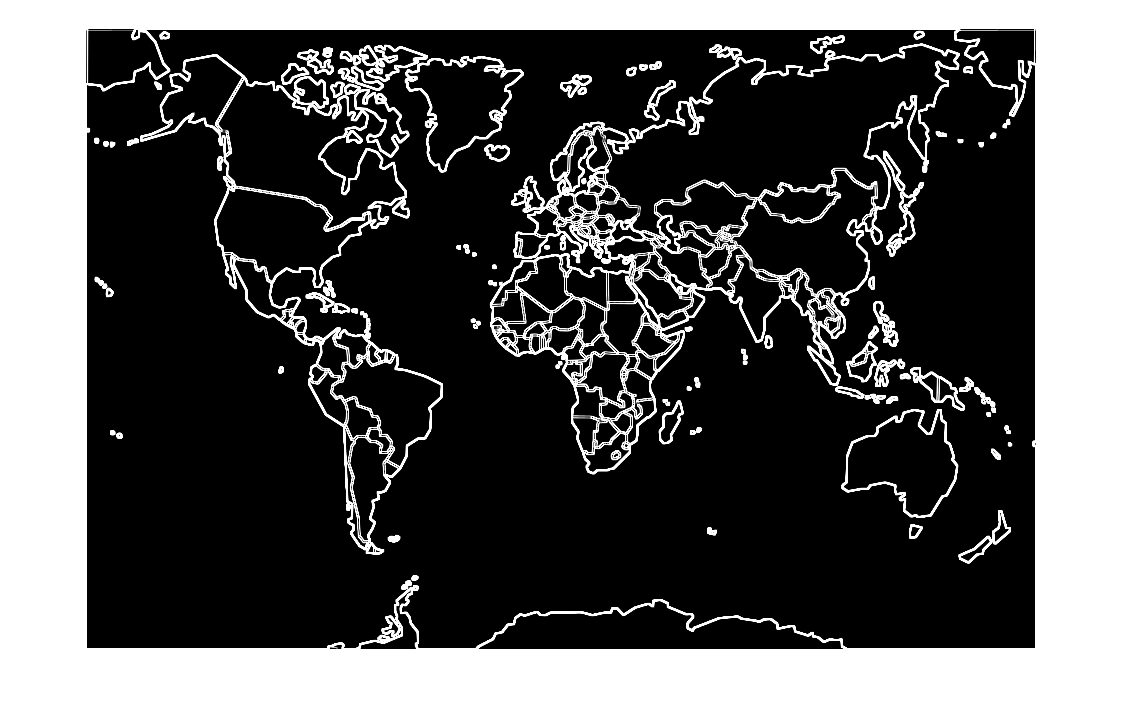

convol(monde, h4, true)

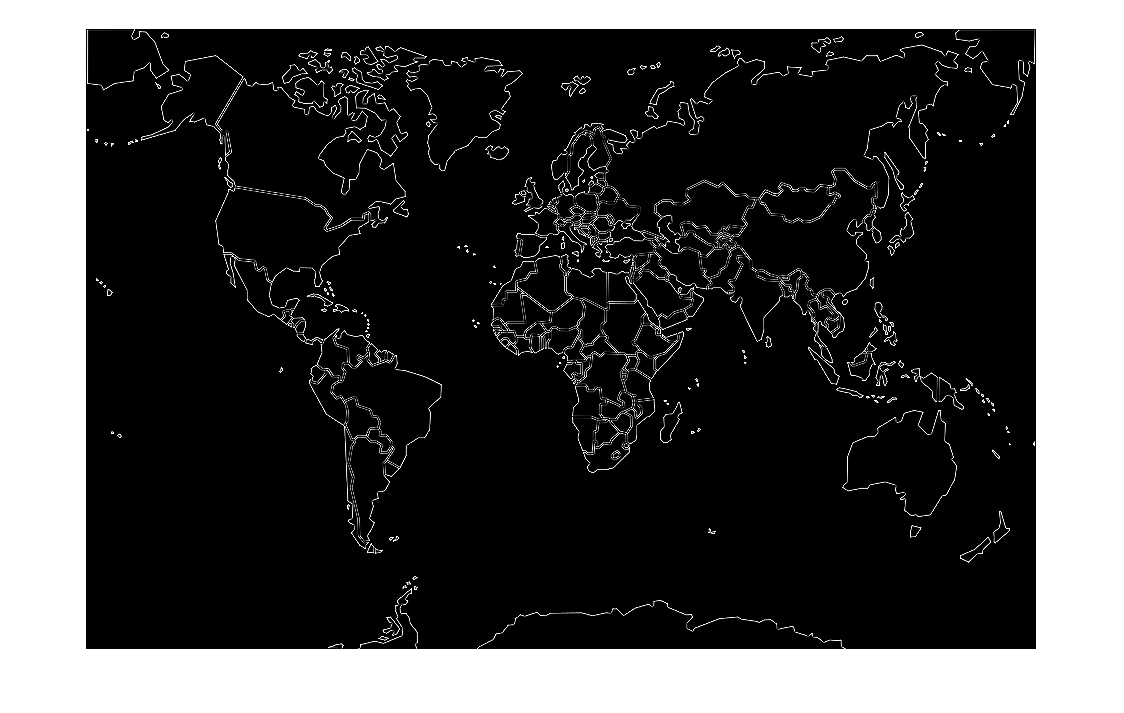

convol(monde, h5, false)

### Augmentation du contraste de l'image

image = lena;
contraste = image - uint8(convol_in(image, h5, false));

ans =      2     2


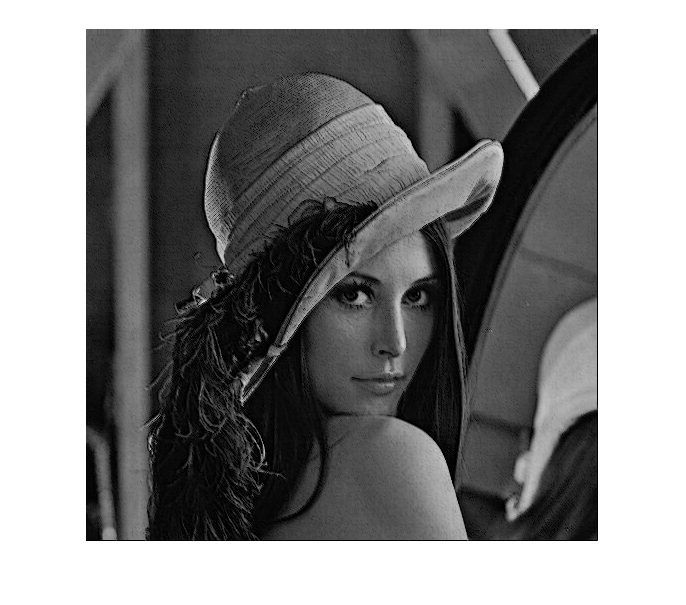

imshow(contraste)

imshow(image)

## Filtres passe bas

h1 = (1/9) * [[1 1 1];[1 1 1];[1 1 1]]

h1 =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


h2 = (1/16) * [[1 2 1];[2 4 2];[1 2 1]]

h2 =     0.0625    0.1250    0.0625
    0.1250    0.2500    0.1250
    0.0625    0.1250    0.0625


### Application des filtres H1 et H2

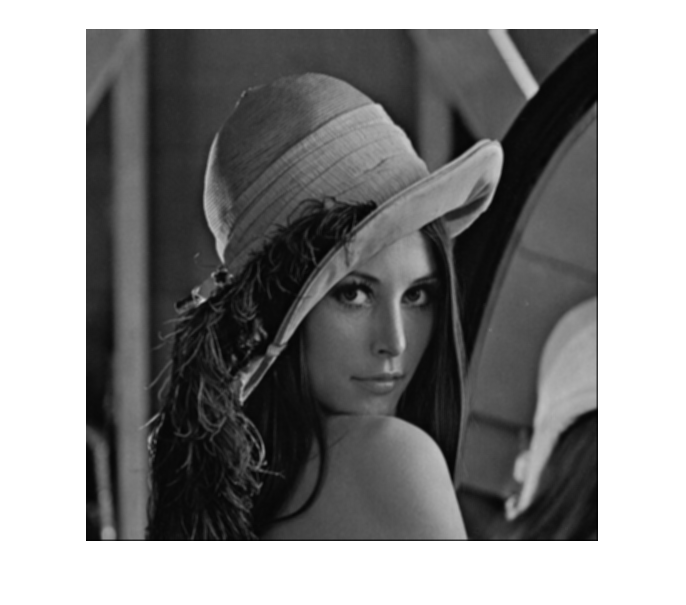

convol(lena, h1, false)

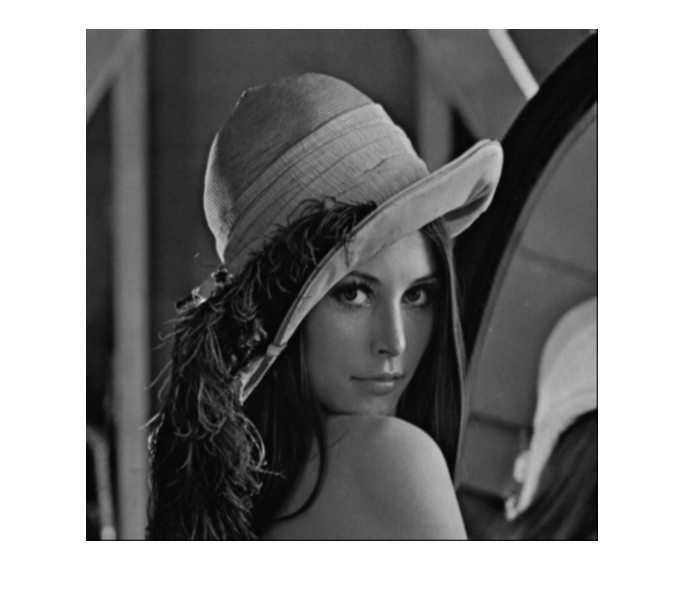

convol(lena, h2, false)

### Différences avec le sur-échantillonnage

% Différences with TP1

### Augmentation de la taille de H1

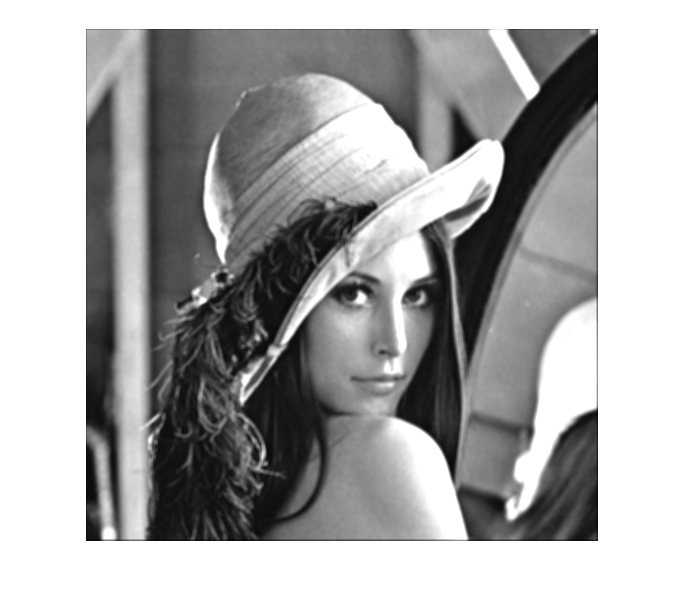

convol(lena, expand_mask(h1, 1), false)

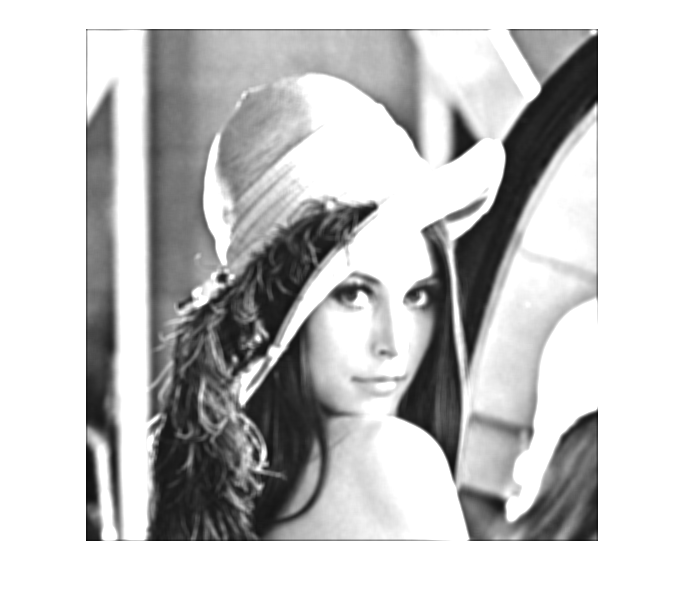

convol(lena, expand_mask(h1, 2), false)

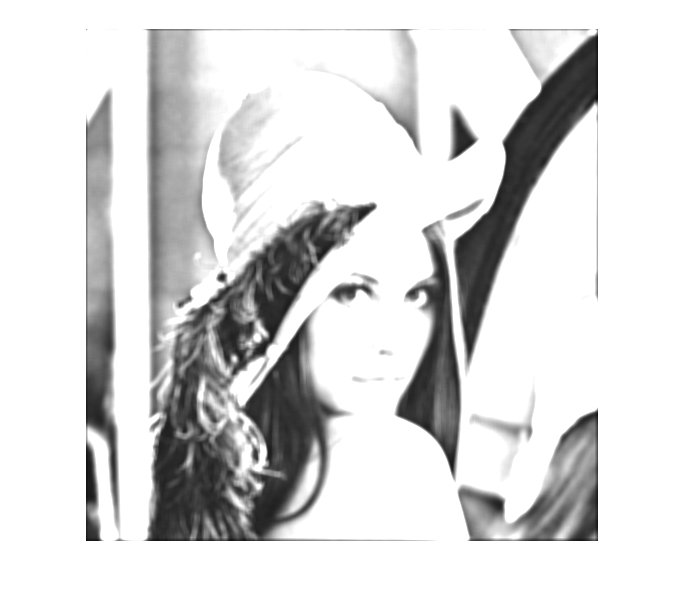

convol(lena, expand_mask(h1, 3), false)

Le fait d'augmenter la taille du filtre H1 éclaircit énormément l'image. En effet, augmenter la taille du filtre augmente le nombre de pixels adjacents pris en compte dans le calcul de la "moyenne".

## Fonctions utilitaires

function img = convol_in(img, filtre, with_transpo)
    % Applique le filtre à l'image et applique également sa transposée si
    % 'with_transpo' == True
    convol1 = conv2(img, filtre, 'same');
    if(with_transpo)
        convol2 = conv2(img', filtre, 'same');
        img = sqrt(power(convol1, 2) + power(convol2', 2));
    else
        img = convol1;
    end
    img = uint8(img);
end

function convol(img, filtre, with_transpo)
    % Applique la convolution et affiche l'image
    a = convol_in(img, filtre, with_transpo);
    imshow(a)
end

function mask = expand_mask(mask, expansion)
    % Augmente la dimension du masque de 'expansion', ne fonctionne qu'avec
    % les masques uniformes (ex: H1)
    % Ex: (3, 3) -> (4, 4)
    val = mask(1,1);
    mask = val * ones(size(mask) + expansion);
end